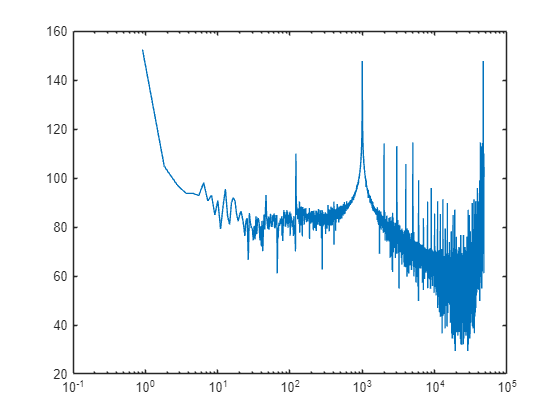

raw = readtable("C:\Users\mpolj\AppData\Local\teraterm5\teraterm.log");
doub = table2array(raw);
bin_d = dec2bin(doub);
tt = size(bin_d);
bin_data = bin_d(:, tt(2)-15-16:tt(2)-16);
%bin_data = bin_d(:, 38-15:38);
%pdm = bin_d(:, 20);
doub_data = typecast(uint16(bin2dec(bin_data)), 'int16');
%q = [16 0];
%doub_data = bin2num(q, bin_data');
%dub_data = typecast(doub_data, 'double');
doub_data(abs(doub_data)>5000000) = 0;
fft_f = fft(doub_data);
fft_f_abs = db(abs(fft_f));
%tmp = 2500000/8/2/2/2/length(fft_f_abs)*(1:length(fft_f_abs));
tmp = 3072000/8/2/2/2/length(fft_f_abs)*(1:length(fft_f_abs));
figure()
semilogx(tmp, fft_f_abs)

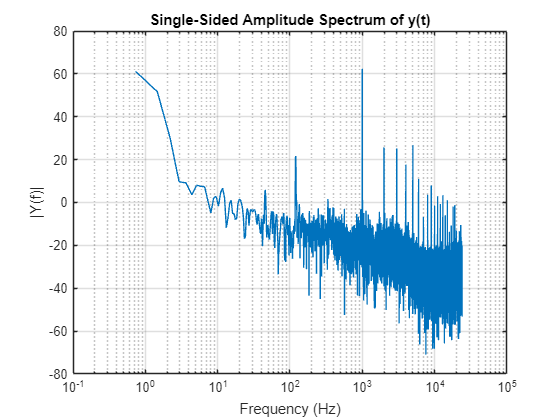

fft_plot(double(doub_data), 3072000/8/2/2/2, 'log', 'dB', @blackman);

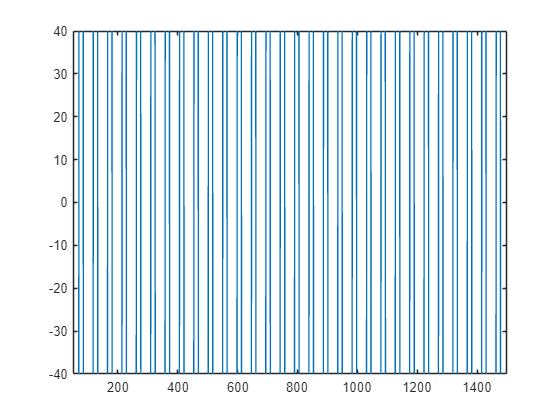

%fft_plot(double(doub_data), 2500000/8/2/2/2, 'log', 'dB', @blackman);
file_Name = "TestData2.txt";
%bin_T = table(bin2dec(bin_d(:, 21)));
%writetable(bin_T, file_Name);
fig = figure();
%fig.Position(3:4) = [1000, 200];
bu = 1:length(doub_data);
plot(bu, doub_data)
xlim([50 1500])
ylim([-40 40])

bin_data2 = bin_d(:, :);
doub_data2 = typecast(uint16(bin2dec(bin_data2)), 'int16');

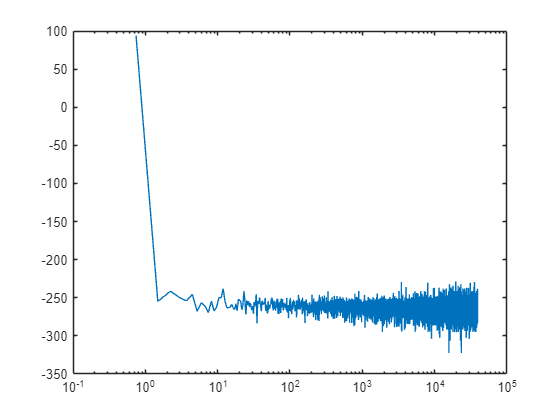

doub_data2(abs(doub_data2)>500000) = 0;
fft_f2 = fft(doub_data2);
fft_f_abs2 = db(abs(fft_f2));
tmp2 = 2500000/8/2/2/2/length(fft_f_abs2)*(1:length(fft_f_abs2));
figure()
semilogx(tmp2, fft_f_abs2)

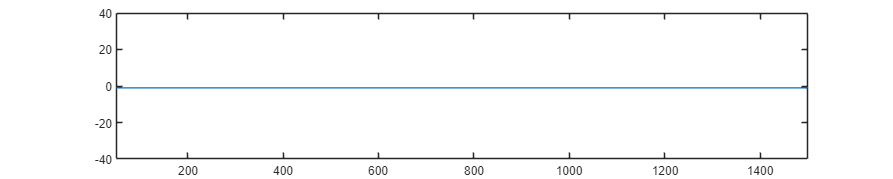

fig2 = figure();
fig2.Position(3:4) = [1000, 200];
bu2 = 1:length(doub_data2);
plot(bu2, doub_data2)
xlim([50 1500])
ylim([-40 40])

%remove dc offset and funny spikes
NUMS = [1, -1, 0.996]

NUMS =     1.0000   -1.0000    0.9960


F_len = 9;
FUL_len = 16;
fixed_NUMS = sfi(NUMS, FUL_len+F_len, F_len)

fixed_NUMS =     1.0000   -1.0000    0.9961

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 25
        FractionLength: 9

bin_fixed_NUMS = bin(fixed_NUMS)

bin_fixed_NUMS = '0000000000000001000000000   1111111111111111000000000   0000000000000000111111110'


audiowrite(['ZedBoard_uart_ic.wav'], rescale(double(doub_data), -1, 0.99), 2000000/8/2/2/2)
%sound(double(doub_data), 2500000/NN/2/2/2);


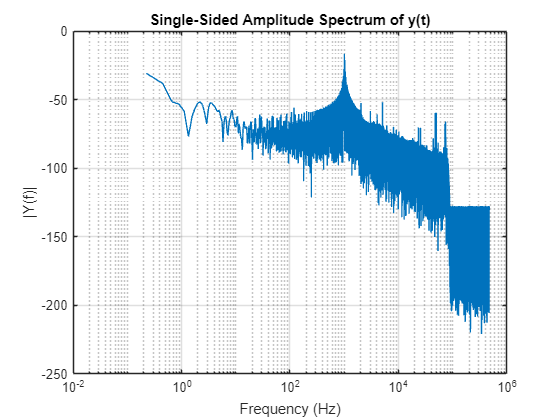

[imp_sound,fs1] = audioread("1000_v2.wav");

fft_plot(imp_sound, fs1*21.3, 'log', 'dB', @blackman);

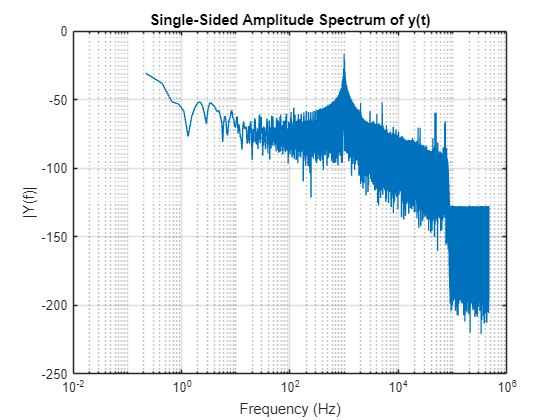

audiowrite("1000_v2_res.wav", imp_sound, fs1*21);

[imp_sound_res,fs1_res] = audioread("1000_v2_res.wav");
fft_plot(imp_sound_res, fs1_res, 'log', 'dB', @blackman);

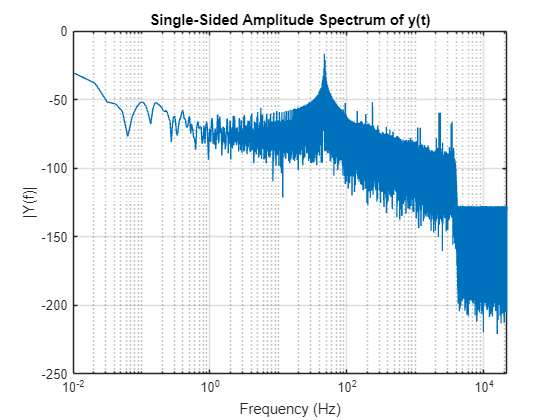



[imp_sound2,fs2] = audioread("1000_v2.wav");
fft_plot(imp_sound2, fs2, 'log', 'dB', @blackman);


fft_plot(imp_sound2, fs1, 'log', 'dB', @blackman);

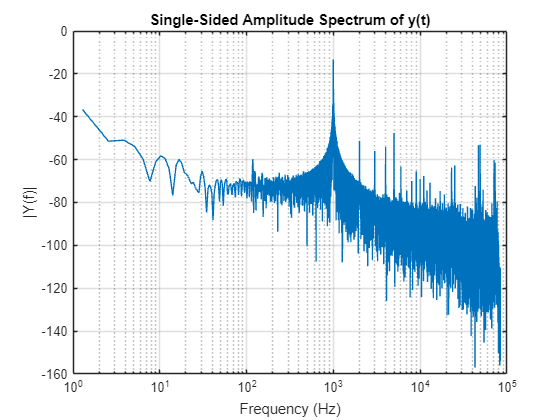

[imp_sound3,fs3] = audioread("1000_V3.wav");
fft_plot(imp_sound3, fs3*21, 'log', 'dB', @blackman);

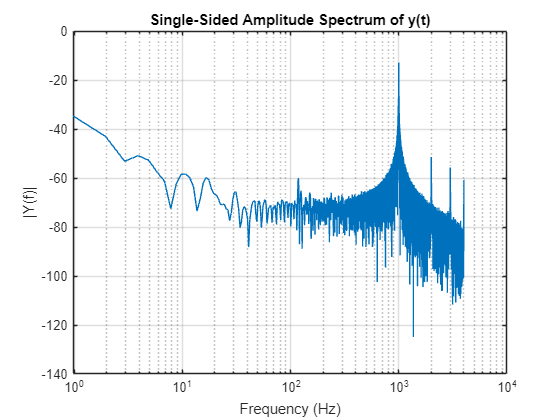


imp3_res = resample(imp_sound3, 1, 21);
fft_plot(imp3_res, fs3, 'log', 'dB', @blackman);

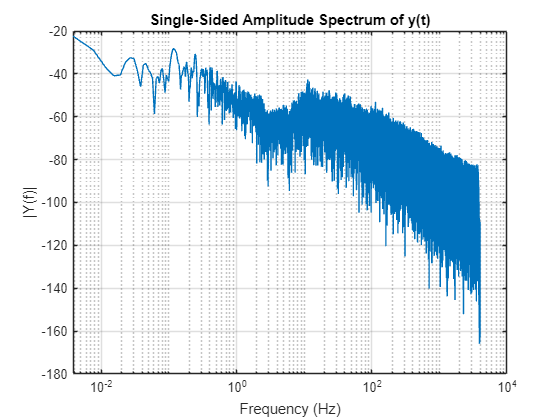

audiowrite("1000_V3_res.wav", imp3_res, fs3);

[never_gonna_give_you_up_V1,fs_ngu] = audioread("never_gonna_give_you_up_V1.wav");
never_gonna_give_you_up_res_V1 = resample(never_gonna_give_you_up_V1, 1, 21);
audiowrite("never_gonna_give_you_up_res_V1.wav", never_gonna_give_you_up_V1, 96000);

[never_gonna_give_you_up_V2,fs_ngu0] = audioread("never_gonna_give_you_up_V2.wav");
audiowrite("never_gonna_give_you_up_V2_res.wav", never_gonna_give_you_up_V2, 108000);%112000);

[i1000V4,fs_V4] = audioread("1000_V4.wav");
never_gonna_give_you_up_res_V22 = resample(never_gonna_give_you_up_V1, 1, 21);
fft_plot(i1000V4, fs_V4, 'log', 'dB', @blackman);

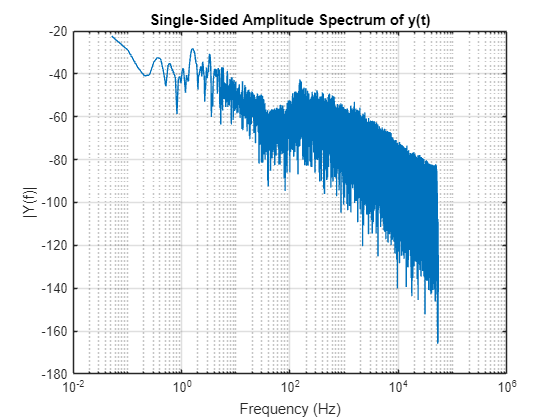

audiowrite("i1000V4.wav", i1000V4, 108000);
[i1000V4__,fs_V4__] = audioread("i1000V4.wav");
fft_plot(i1000V4__, fs_V4__, 'log', 'dB', @blackman);

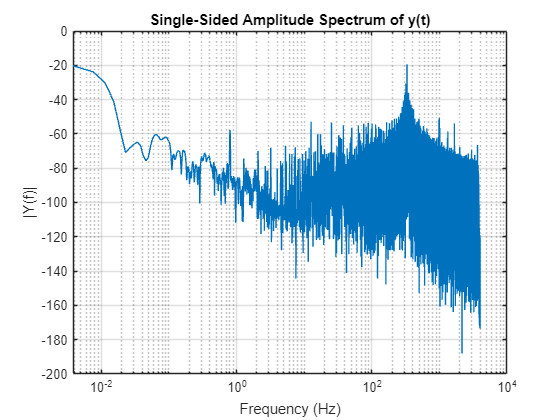

% usb IC testing and resampling
[zedboard_usb_raw_ic,fs_usb] = audioread("zedboard_usb_raw_ic.wav");
fft_plot(zedboard_usb_raw_ic, fs_usb, 'log', 'dB', @blackman);

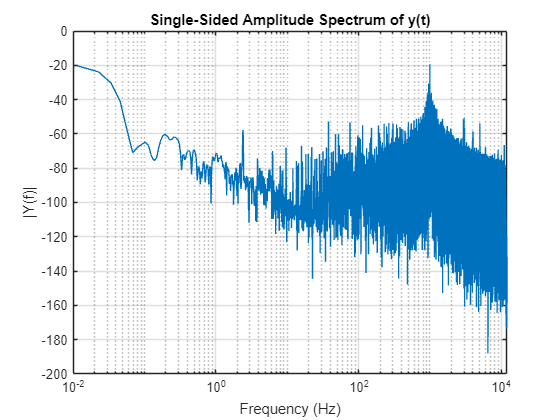

audiowrite("zedboard_usb_res_ic.wav", zedboard_usb_raw_ic, 48000/2);
[zedboard_usb_res_ic,fs_usb_res] = audioread("zedboard_usb_res_ic.wav");
fft_plot(zedboard_usb_res_ic, fs_usb_res, 'log', 'dB', @blackman);

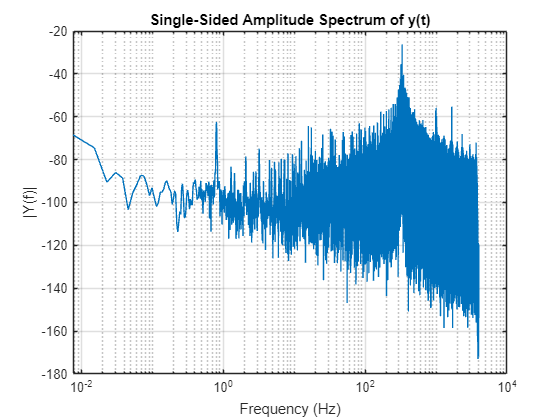

% usb FIR decimation testing and resampling
[zedboard_usb_raw_fir,fs_usb_fir] = audioread("zedboard_usb_raw_fir.wav");
fft_plot(zedboard_usb_raw_fir, fs_usb_fir, 'log', 'dB', @blackman);

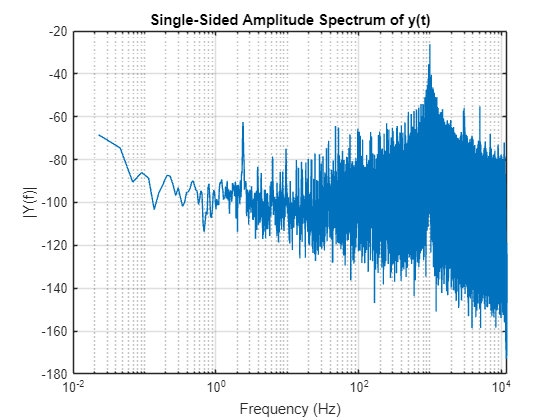

audiowrite("zedboard_usb_res_fir.wav", zedboard_usb_raw_fir, 48000/2);
[zedboard_usb_res_fir,fs_usb_fir_res] = audioread("zedboard_usb_res_fir.wav");
fft_plot(zedboard_usb_res_fir, fs_usb_fir_res, 'log', 'dB', @blackman);

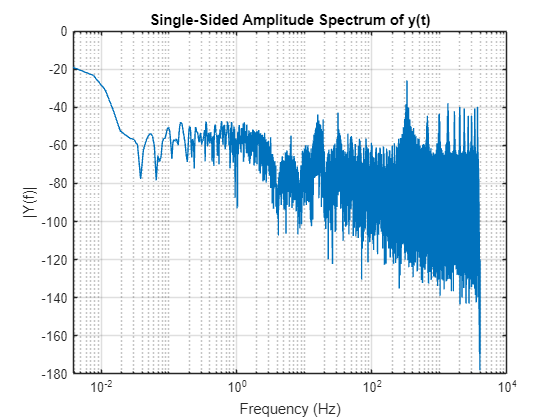

% usb halfband decimation testing and resampling
[zedboard_usb_raw_hbf,fs_usb_hbf] = audioread("zedboard_usb_raw_hbf.wav");
fft_plot(zedboard_usb_raw_hbf, fs_usb_hbf, 'log', 'dB', @blackman);

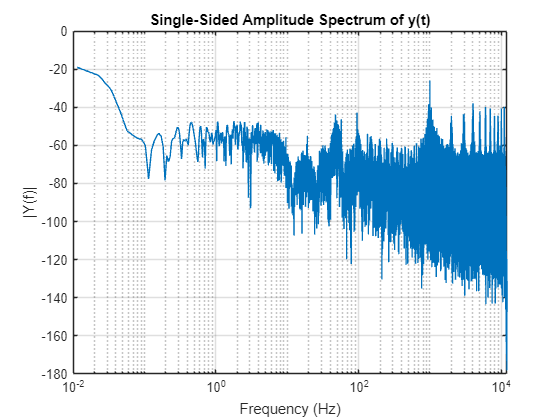

audiowrite("zedboard_usb_res_hbf.wav", zedboard_usb_raw_hbf, 48000/2);
[zedboard_usb_res_hbf,fs_usb_hbf_res] = audioread("zedboard_usb_res_hbf.wav");
fft_plot(zedboard_usb_res_hbf, fs_usb_hbf_res, 'log', 'dB', @blackman);

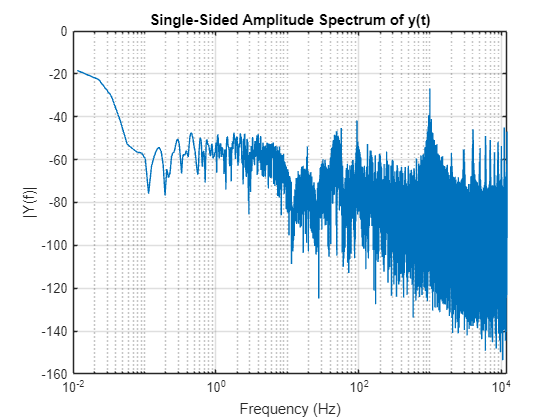

zedboard_usb_res_hbf(abs(zedboard_usb_res_hbf)>0.3) = 0;
fft_plot(zedboard_usb_res_hbf, fs_usb_hbf_res, 'log', 'dB', @blackman);

audiowrite("zedboard_usb_res_hbf_fixed.wav", zedboard_usb_res_hbf, 48000/2);

x_dir = [32,1,45,15,1,26,5,38,17,1,27,5,42,17,0,25,1,40,11,0,23,40,15,0,22,3,36,8,0,22];
y_dir = [33,35,43,36,3,40,21,48,23,0,33,21,40,23,0,43,30,46,31,0,35,46,26,0,35,13,45,31,0,35];

x_loc = mean(x_dir)

x_loc = 17.2667

y_loc = mean(y_dir)

y_loc = 27.1667